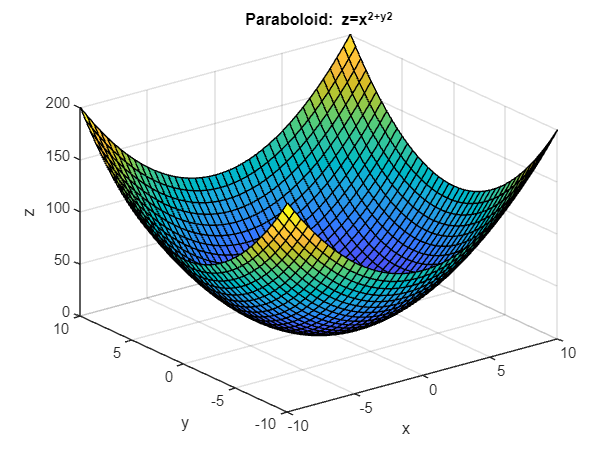

X=-10:0.5:10;
Y=-10:0.5:10;
[X,Y]=meshgrid(X,Y);
Z=X.^2+Y.^2;
surf(X,Y,Z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloid: z=x^2+y^2')

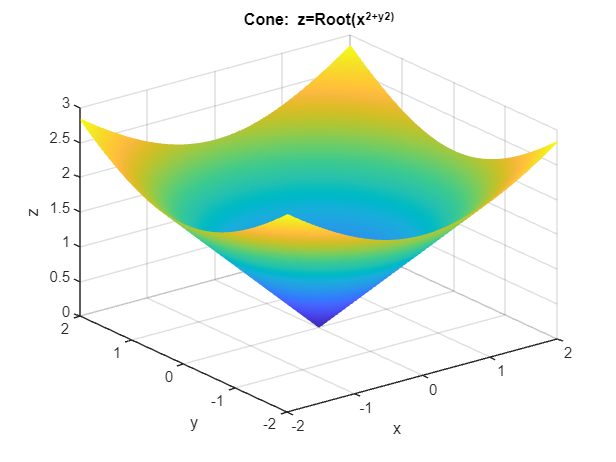

clf
clear all
X=-2:0.01:2;
Y=-2:0.01:2;
[X,Y]=meshgrid(X,Y);
Z=sqrt(X.^2+Y.^2);
mesh(X,Y,Z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Cone: z=Root(x^2+y^2)')

clf
clear all
syms t
x=4*cos(t);
y=4*sin(t);
r(t)=[x y]

$$r(t) = \left(\begin{array}{cc} 4\,\cos\left(t\right) & 4\,\sin\left(t\right) \end{array}\right)$$

v(t)=diff(r(t),t)

$$v(t) = \left(\begin{array}{cc} -4\,\sin\left(t\right) & 4\,\cos\left(t\right) \end{array}\right)$$

V(t)=subs(v(t),t,pi)

$$V(t) = \left(\begin{array}{cc} 0 & -4 \end{array}\right)$$


a(t)=diff(v(t),t)

$$a(t) = \left(\begin{array}{cc} -4\,\cos\left(t\right) & -4\,\sin\left(t\right) \end{array}\right)$$

A(t)=subs(a(t),t,pi)

$$A(t) = \left(\begin{array}{cc} 4 & 0 \end{array}\right)$$

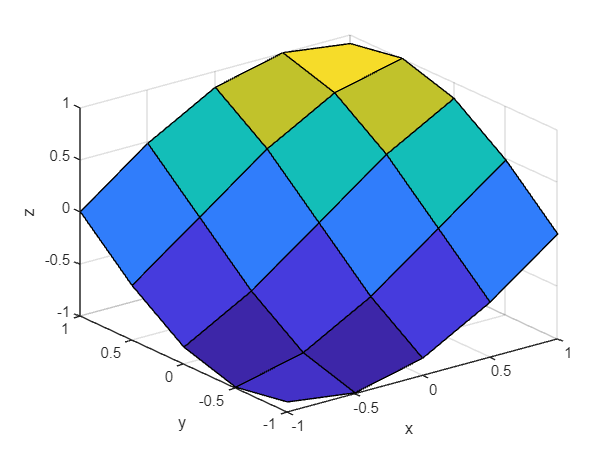

%Practise Questions
%1)
%i)
clf
clear all
x=-1:0.5:1;
y=-1:0.5:1;
[x,y]=meshgrid(x,y);
z=sin(x+y);
surf(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')

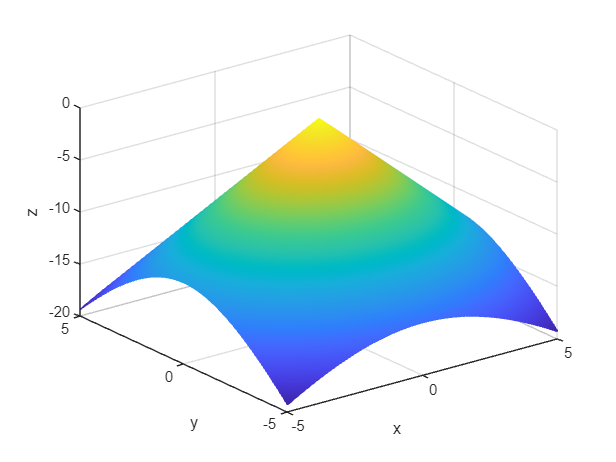

%(ii)
clf
clear all
x=-5:0.01:5;
y=-5:0.01:5;
[x,y]=meshgrid(x,y);
z=-sqrt(6*x.^2+9*y.^2);
mesh(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')

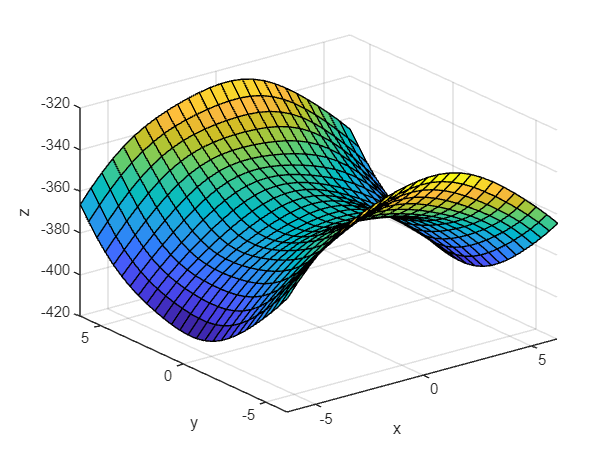

%(iii)
clf
clear all
x=-2*pi:0.5:2*pi;
y=-2*pi:0.5:2*pi;
[x,y]=meshgrid(x,y);
z=sin(x+y)-x.^2-x*y+y.^2;
surf(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')

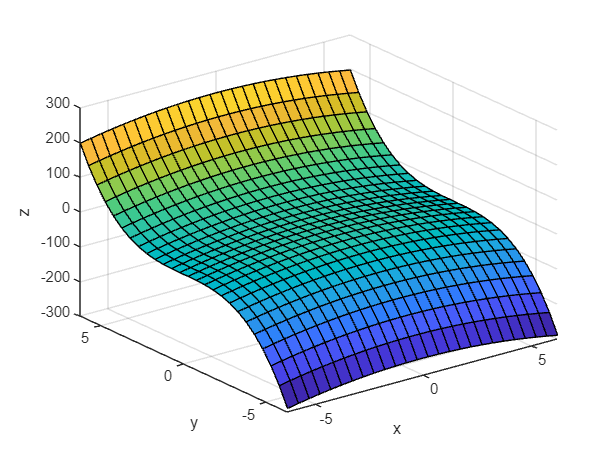

%(iv)
clf
clear all
x=-2*pi:0.5:2*pi;
y=-2*pi:0.5:2*pi;
[x,y]=meshgrid(x,y);
z=cos(25*x)-x.^2+y.^3-5;
surf(x,y,z);
xlabel('x')
ylabel('y')
zlabel('z')

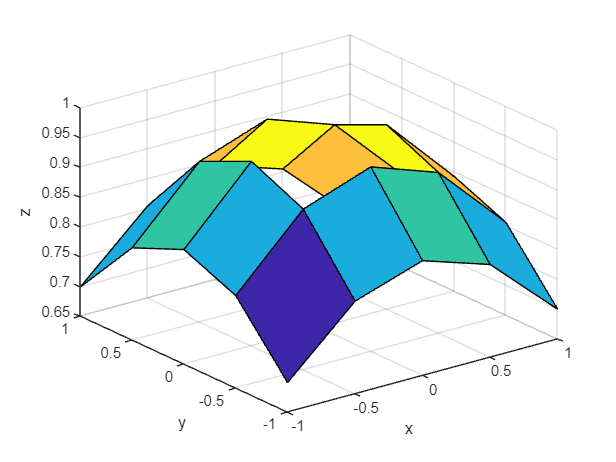

%(v)
clf
clear all
x=-1:0.5:1;
y=-1:0.5:1;
[x,y]=meshgrid(x,y);
z=(sin(sqrt(x.^2+y.^2)))./(sqrt(x.^2+y.^2));
surf(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')

%2)
%(i)
clf
clear all
syms t
r(t)=[t,t.^2,0];
v(t)=diff(r(t),t);
V(t)=subs(v(t),t,3)

$$V(t) = \left(\begin{array}{ccc} 1 & 6 & 0 \end{array}\right)$$

a(t)=diff(v(t),t);
A(t)=subs(a(t),t,3)

$$A(t) = \left(\begin{array}{ccc} 0 & 2 & 0 \end{array}\right)$$

%(ii)
clf
clear all
syms t
r(t)=[8*t,6*t,0];
v(t)=diff(r(t),t);
V(t)=subs(v(t),t,6)

$$V(t) = \left(\begin{array}{ccc} 8 & 6 & 0 \end{array}\right)$$

a(t)=diff(v(t),t);
A(t)=subs(a(t),t,6)

$$A(t) = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

%(iii)
clf
clear all
syms t
r(t)=[cos(t),2*sin(t),0];
v(t)=diff(r(t),t);
V(t)=subs(v(t),t,(3*pi)/2)

$$V(t) = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

a(t)=diff(v(t),t);
A(t)=subs(a(t),t,(3*pi)/2)

$$A(t) = \left(\begin{array}{ccc} 0 & 2 & 0 \end{array}\right)$$

%(iv)
clf 
clear all
syms t
r(t)=[cos(t),sin(t),9*t];
v(t)=diff(r(t),t);
V(t)=subs(v(t),t,pi/2)

$$V(t) = \left(\begin{array}{ccc} -1 & 0 & 9 \end{array}\right)$$

a(t)=diff(v(t),t);
A(t)=subs(a(t),t,pi/2)

$$A(t) = \left(\begin{array}{ccc} 0 & -1 & 0 \end{array}\right)$$